# Spring Loaded Inverted Pendulum (SLIP) Simulation

clear;clc;

slip.l0 = 1; % Length of the spring
slip.th = deg2rad(10); % Touchdown
fps = 20;
deltat = 5;

% Initial Guess
q0 = [0 1.5 1.1 0]; % At Apex

## Poincare Map Fixed Point

options = optimset('TolFun',1e-12,'TolX',1e-12,'MaxIter',700,'MaxFunEvals',700,'Display','off');
[qfixed,val,flag] = fsolve(@(qfixed) qfixed - poincare_map(qfixed,deltat,slip),q0(2:3),options);
if flag == 1
    disp('Successfully Converged.');
    q0 = [0 qfixed 0];
else
    disp('Failed to converge. Modify, IC or PDW parameters.')
end

Successfully Converged.


% Fixed Point Stability
poincare_map_ = @(q) poincare_map(q,deltat,slip);
Jqstar = jacobianest(poincare_map_,qfixed);
eig(Jqstar)

ans =     1.0000
    4.4861


## Integrate

n = 6; % Number of steps
tsim = [];
qsim = [];
tstart = 0;

for k=1:n
    [t,q,q0next] = one_step(tstart,deltat,q0,slip);
    tq = linspace(t(1),t(end),fps)';
    qq(:,1) = interp1(t,q(:,1),tq);
    qq(:,2) = interp1(t,q(:,2),tq);
    qq(:,3) = interp1(t,q(:,3),tq);
    qq(:,4) = interp1(t,q(:,4),tq);
    qq(:,5) = interp1(t,q(:,5),tq);
    qq(:,6) = interp1(t,q(:,6),tq);
    tsim = [tsim; tq(1:end-1,:)];
    qsim = [qsim; qq(1:end-1,:)];
    q0 = q0next;
    tstart = tsim(end,:);
end

## Animate

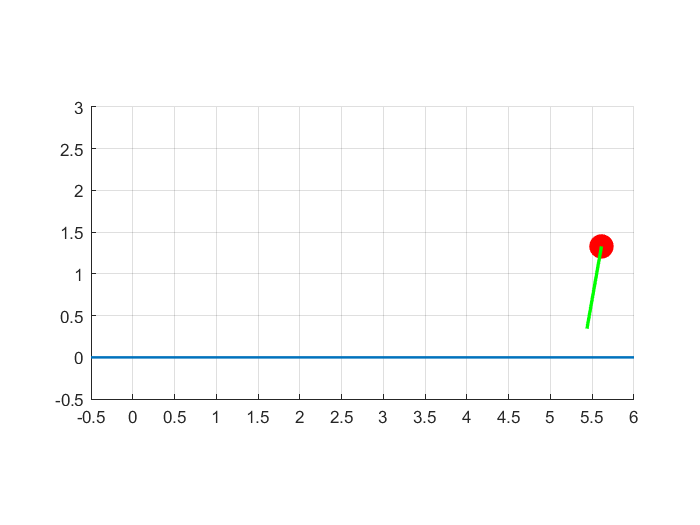

L = 6;

figure(1);
for k=1:length(tsim)
    qk = qsim(k,1:4);
    foot = qsim(k,5:6);
    
    hold on;
    grid on;
    h1 = line([-0.5 L],[0 0],'LineWidth',1.5); % Ground
    h2 = plot(qk(1),qk(2),'.','MarkerSize',50,'Color','red'); % Point Mass
    h3 = line([qk(1) foot(1)],[qk(2) foot(2)],'LineWidth',2,'Color','green'); % Spring
    
    axis([-0.5 L -0.5 L/2]);
    xticks(-0.5:0.5:L);
    yticks(-0.5:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    pause(0.05);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
    end 
end

## Plot SLIP Paramaters

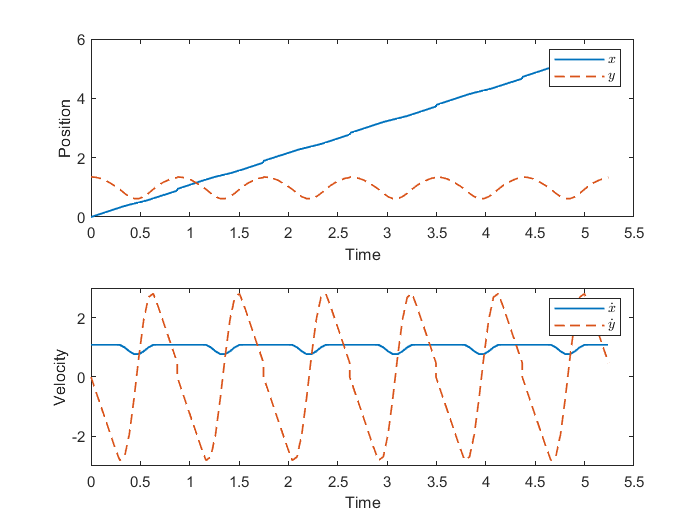

figure(2);
subplot(2,1,1);
plot(tsim,qsim(:,1),'LineWidth',1);
hold on;
plot(tsim,qsim(:,2),'--','LineWidth',1);
ylabel('Position');
xlabel('Time');
axis([0 5.5 0 6]);
legend({'$x$', '$y$'}, 'Interpreter', 'latex');
subplot(2,1,2);
plot(tsim,qsim(:,3),'LineWidth',1);
hold on;
plot(tsim,qsim(:,4),'--','LineWidth',1);
ylabel('Velocity');
xlabel('Time');
axis([0 5.5 -3 3]);
legend({'$\dot{x}$', '$\dot{y}$'}, 'Interpreter', 'latex');